# Digital Signal Processing 

## Special tools:

- busca_maximos: busca todos los maximos de una senyal

- busca_maximosth: busca todos los maximos que superen un umbral

- cumcamsimp: integracion numerica de cavalieri-simpson

- datacrop: herramienta interactiva para recortar una senyal

## Double integral variations:

- doble_cumsum: doble integral 

- doble_cumsum_kose: doble integral (metodo de Kose)

- doble_cumsum_rampp: doble integral (metodo de Rampp)

- doble_cumsum_thong: doble integral (metodo de Thong)

- doble_cumsum_zijlstra: doble integral (metodo de zijlstra)

### busca_maximos

Construimos una señal senoidal a modo de prueba:

t=0:0.1:10;
datos=sin(2*pi*0.5*t);
plot(datos)    

Y realizamos la llamada a la función:

maximos=buscamaximos(datos);

Representamos el resultado gráficamente.

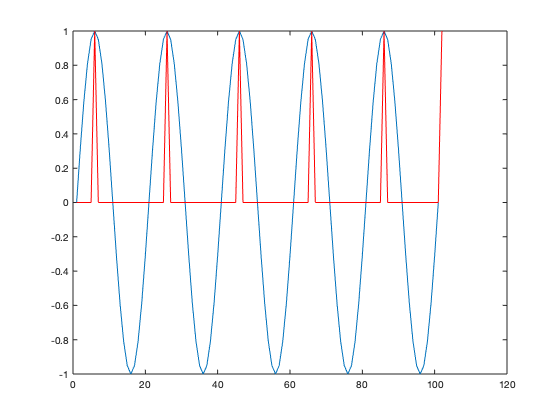

hold on 
plot(maximos,'r');

Si deseamos obtener los índices en los que se producen los máximos podemos hacerlo como:

find(maximos)

ans =      6    26    46    66    86   102


Como siempre en procesamiento de señal se debe prestar especial cuidado al funcionamiento en los bordes. El máximo final, en la muestra 102 probablemente no se deseaba detectarlo.